## Experimenal Case Study on the Smart Road Bridge (Using Standard NOR-BWIM)

The purpose of this code is to use MLE method for weight estimation of some trucks on the smart road bridge in an experimental case study. This code is made specifically for the phase 1 of my PhD project described in chapter 2 of my dissertation. The tests are completely decribed there. So, it is suggested to read this chapter first before considering this code. 

We have two groups of data and trucks. The first group is the tests using the trucks we hired (a 3-axle and a 5-axle). The data for this group is called DataWed.xlsx. Tests 1 through 8 in the following code is related to this group. The second group is the construction trucks that we did not hire them and just asked them to drive with a speed we want and to also report their weights every time they pass over the bridge. The data file is called B.csv. If you see file DataWed.xlsx, we have continuous strain responses for four strain gauges. The strain gauge numbers are shown below. These strain gauges are equivalent to what we have in chapter two in Row 1 that is where max localized strain response happens. For prerequisite estimation we used three strain gauges. However this code is only for weight estimation and for weight estimation only strain gauge 40 was used. On the test day, for each group of trucks, I recorded the time when the desired test truck arrived on the bridge and based on the time I later extracted the associated strain response.

For IL computation, Tests 5-9 were used that are all 3-axle trucks and the remaining truck passages (14 tests) were used for weight estimation. The weights reported in my dissertation are in tons and the computation here is in Kips. So, the numbers here should be multiplied by 0.455 to become the numbers in chapter 2 of my dissertation.

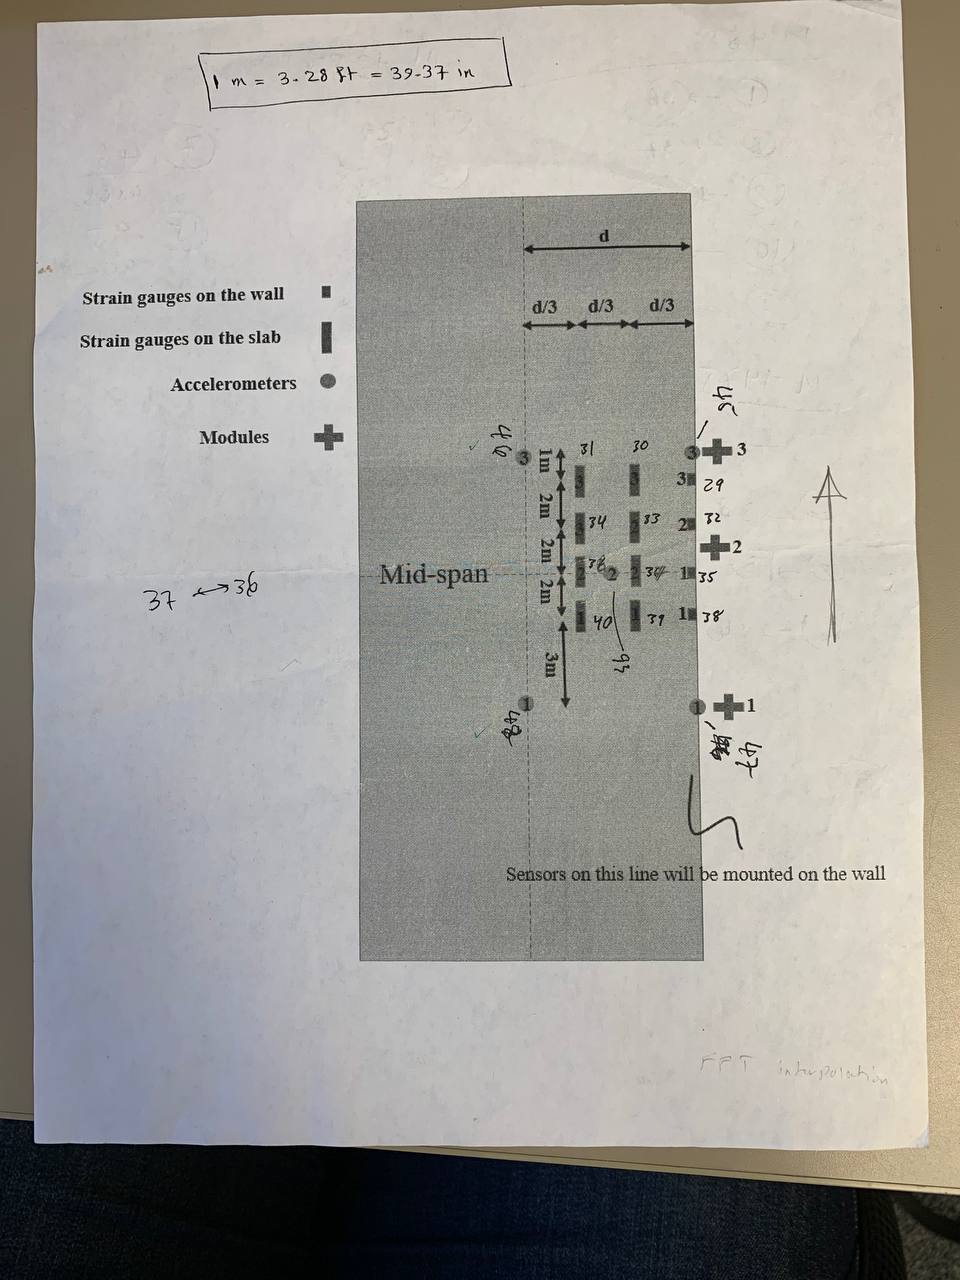

In this code, two functions are needed, one for A_MATRIX and one for B_MATRIX. Please see chapter 2 in my disertation for their definitions. Make sure that these two functions are beside the main code. In all codes A_MATRIX and B_MATRIX are not needed to be changed and they are the same for all codes. In this code I have commented the first test (Test 1) and other tests will be similar.

clear;
close;
clc;


Here the continuous strain responses for four strain gauges (for the first group of trucks) are loaded. 

A=readtimetable('DataWed.csv');
datetime.setDefaultFormats('default','hh:mm:ss.SSS')
A.Time

ans = 1048571×1 datetime array
   12:59:55.150
   12:59:55.155
   12:59:55.160
   12:59:55.165
   12:59:55.170
   12:59:55.175
   12:59:55.180
   12:59:55.185
   12:59:55.190
   12:59:55.195
   12:59:55.200
   12:59:55.205
   12:59:55.210
   12:59:55.215
   12:59:55.220
   12:59:55.225
   12:59:55.230
   12:59:55.235
   12:59:55.240
   12:59:55.245
   12:59:55.250
   12:59:55.255
   12:59:55.260
   12:59:55.265
   12:59:55.270
   12:59:55.275
   12:59:55.280
   12:59:55.285
   12:59:55.290
   12:59:55.295


Here, we extract the strain response associated with each test and denoise it using wavelet denoising technique. To remove the temperature effect, it was ideal to have some thermocouples to find the temperature change pattern. However, since there was no thermocouple, we kept a relatively long chunk of strain response before the strain response associated with the truck (see the graph below) and zeroed the response then detrended the signal in a way that the chunk becomes a relatively horizental rsignal starting at zero. This is because when we remove the temperature, it is expected to have zero strain when no truck is on the bridge (long chunk of strain).

## Test 1 (5-axle and 50 mph)

Test 1 was a 5-axle truck with 50 mph speed. 

Test1_st40=(-521.2*521.2*0.001)*A.st40(10998:16498);
Test1_st40 = wdenoise(Test1_st40,5,'DenoisingMethod','BlockJS');
Test1_st40=detrend(Test1_st40,2);
Test1_st40=Test1_st40-mean(Test1_st40(1:500));

Lets plot the strain response when it is denoised and temperature change is removed.

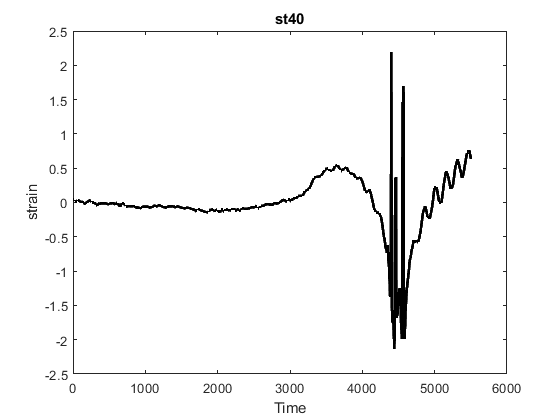

figure
plot(Test1_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

Here we get the truck information. Please see the first paper (experimental case study) or my PhD dissertation (chapter 2) for details and to know what these parameters are. I have also commented them below for clarification

N_T1=5;          %% the number of axles
v1_T1=23.07;     %% speed m/s
f_T1=200;        %% sampling rate (Hz)
d1_T1=0;         %% the distance of the first axle from the first axle (m) --> This is always zero
d2_T1=6.15;      %% the distance of the second axle from the first axle (m) 
d3_T1=1.38;      %% the distance of the third axle from the first axle (m) 
d4_T1=10.69;     %% the distance of the fourth axle from the first axle (m) 
d5_T1=1.23;      %% the distance of the fifth axle from the first axle (m) 

% Axle weights

Weights_T1=[12.300 12.520 12.520 11.100 11.100];

% D vector using the d values already defined 

D1_vec_T1=[d1_T1 d1_T1+d2_T1 d1_T1+d2_T1+d3_T1 d1_T1+d2_T1+d3_T1+d4_T1 d1_T1+d2_T1+d3_T1+d4_T1+d5_T1];

% Calculating c values based on speed, sampling rate, and d values

c1_T1=D1_vec_T1(1)*f_T1/v1_T1;
c2_T1=D1_vec_T1(2)*f_T1/v1_T1;
c3_T1=D1_vec_T1(3)*f_T1/v1_T1;
c4_T1=D1_vec_T1(4)*f_T1/v1_T1;
c5_T1=D1_vec_T1(5)*f_T1/v1_T1;

C1_vec_T1=round([c1_T1 c2_T1 c3_T1 c4_T1 c5_T1]);

[row1_T1 col1_T1]=size(Test1_st40);         
k1_T1=row1_T1;                      %% Total number of scans


This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data) and returns the Matrix A. This matrix is later used for IL computation.

[A_mat_T1]=A_MATRIX(N_T1,k1_T1,C1_vec_T1,Weights_T1);


## Test 2 (5-axle and 50 mph)

The comments for the remaining tests are similar to Test 1.

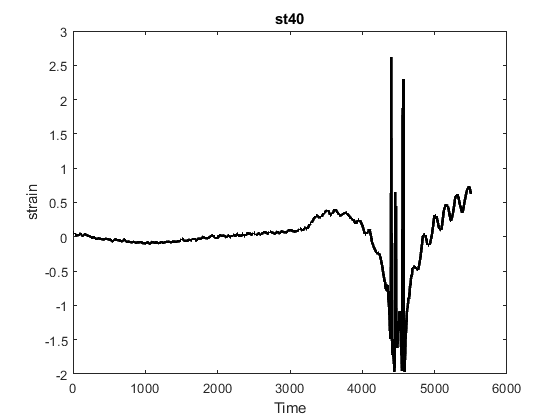

Test2_st40=(-521.2*521.2*0.001)*A.st40(70685:76186);
Test2_st40 = wdenoise(Test2_st40,5,'DenoisingMethod','BlockJS');
Test2_st40=detrend(Test2_st40,2);
Test2_st40=Test2_st40-mean(Test2_st40(1:500));


figure

plot(Test2_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_T2=5;          %% the number of axles
v1_T2=22.94;     %% m/s
f_T2=200;        %% Hz
d1_T2=0;         %% m
d2_T2=6.19;      %% m
d3_T2=1.34;      %% m
d4_T2=10.71;     %% m
d5_T2=1.26;      %% m


Weights_T2=[12.300 12.520 12.520 11.100 11.100];


D1_vec_T2=[d1_T2 d1_T2+d2_T2 d1_T2+d2_T2+d3_T2 d1_T2+d2_T2+d3_T2+d4_T2 d1_T2+d2_T2+d3_T2+d4_T2+d5_T2];

c1_T2=D1_vec_T2(1)*f_T2/v1_T2;
c2_T2=D1_vec_T2(2)*f_T2/v1_T2;
c3_T2=D1_vec_T2(3)*f_T2/v1_T2;
c4_T2=D1_vec_T2(4)*f_T2/v1_T2;
c5_T2=D1_vec_T2(5)*f_T2/v1_T2;

C1_vec_T2=round([c1_T2 c2_T2 c3_T2 c4_T2 c5_T2]);

[row1_T2 col1_T2]=size(Test2_st40);         
k1_T2=row1_T2;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T2]=A_MATRIX(N_T2,k1_T2,C1_vec_T2,Weights_T2);


## Test 3 (5-axle and 30 mph)

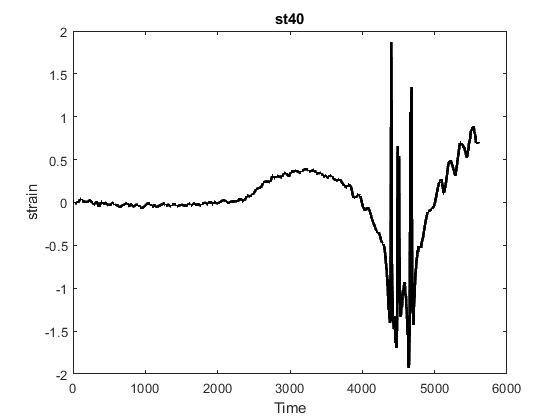

Test3_st40=(-521.2*521.2*0.001)*A.st40(131584:137195);
Test3_st40 = wdenoise(Test3_st40,5,'DenoisingMethod','BlockJS');
Test3_st40=detrend(Test3_st40,2);
Test3_st40=Test3_st40-mean(Test3_st40(1:500));
% Time3_st40=A.Time(131587:140698);

figure
% plot(Time3_st40,Test3_st40,'k', 'Linewidth', 2)
plot(Test3_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_T3=5;          %% the number of axles
v1_T3=13.8;     %% m/s
f_T3=200;         %% Hz
d1_T3=0;         %% m
d2_T3=6.14;      %% m
d3_T3=1.31;      %% m
d4_T3=10.63;     %% m
d5_T3=1.24;      %% m
Weights_T3=[12.300 12.520 12.520 11.100 11.100];
% Weights_T3=[10.76120268 9.802096909 10.75691735 11.49913559 14.03314438];
D1_vec_T3=[d1_T3 d1_T3+d2_T3 d1_T3+d2_T3+d3_T3 d1_T3+d2_T3+d3_T3+d4_T3 d1_T3+d2_T3+d3_T3+d4_T3+d5_T3];

c1_T3=D1_vec_T3(1)*f_T3/v1_T3;
c2_T3=D1_vec_T3(2)*f_T3/v1_T3;
c3_T3=D1_vec_T3(3)*f_T3/v1_T3;
c4_T3=D1_vec_T3(4)*f_T3/v1_T3;
c5_T3=D1_vec_T3(5)*f_T3/v1_T3;

C1_vec_T3=round([c1_T3 c2_T3 c3_T3 c4_T3 c5_T3]);

[row1_T3 col1_T3]=size(Test3_st40);         
k1_T3=row1_T3;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T3]=A_MATRIX(N_T3,k1_T3,C1_vec_T3,Weights_T3);


## Test 4 (5-axle and 30 mph)

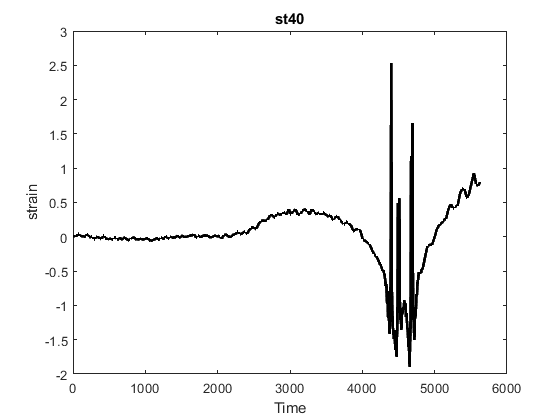

Test4_st40=(-521.2*521.2*0.001)*A.st40(184071:189696);
Test4_st40 = wdenoise(Test4_st40,5,'DenoisingMethod','BlockJS');
Test4_st40=detrend(Test4_st40,2);
Test4_st40=Test4_st40-mean(Test4_st40(1:500));


figure
plot(Test4_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_T4=5;          %% the number of axles

v1_T4=13.29;     %% m/s
f_T4=200;         %% Hz
d1_T4=0;         %% m
d2_T4=6.18;      %% m
d3_T4=1.33;      %% m
d4_T4=10.77;     %% m
d5_T4=1.26;      %% m




Weights_T4=[12.300 12.520 12.520 11.100 11.100];


D1_vec_T4=[d1_T4 d1_T4+d2_T4 d1_T4+d2_T4+d3_T4 d1_T4+d2_T4+d3_T4+d4_T4 d1_T4+d2_T4+d3_T4+d4_T4+d5_T4];

c1_T4=D1_vec_T4(1)*f_T4/v1_T4;
c2_T4=D1_vec_T4(2)*f_T4/v1_T4;
c3_T4=D1_vec_T4(3)*f_T4/v1_T4;
c4_T4=D1_vec_T4(4)*f_T4/v1_T4;
c5_T4=D1_vec_T4(5)*f_T4/v1_T4;

C1_vec_T4=round([c1_T4 c2_T4 c3_T4 c4_T4 c5_T4]);

[row1_T4 col1_T4]=size(Test4_st40);         
k1_T4=row1_T4;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T4]=A_MATRIX(N_T4,k1_T4,C1_vec_T4,Weights_T4);


## Test 5 (3-axle and 50 mph)

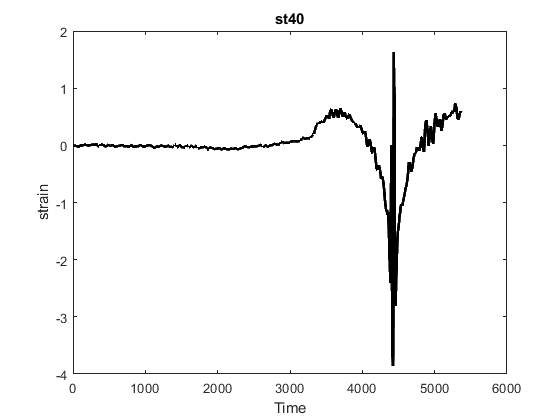



Test5_st40=(-521.2*521.2*0.001)*A.st40(307474:312849);
Test5_st40 = wdenoise(Test5_st40,5,'DenoisingMethod','BlockJS');
Test5_st40=detrend(Test5_st40,2);
Test5_st40=Test5_st40-mean(Test5_st40(1:500));


figure

plot(Test5_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_T5=3;          %% the number of axles
v1_T5=27.91;     %% m/s
f_T5=200;         %% Hz
d1_T5=0;         %% m
d2_T5=5.07;      %% m
d3_T5=1.12;      %% m



Weights_T5=[15.600 21.280 21.280];

D1_vec_T5=[d1_T5 d1_T5+d2_T5 d1_T5+d2_T5+d3_T5];

c1_T5=D1_vec_T5(1)*f_T5/v1_T5;
c2_T5=D1_vec_T5(2)*f_T5/v1_T5;
c3_T5=D1_vec_T5(3)*f_T5/v1_T5;

C1_vec_T5=round([c1_T5 c2_T5 c3_T5]);

[row1_T5 col1_T5]=size(Test5_st40);         
k1_T5=row1_T5;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T5]=A_MATRIX(N_T5,k1_T5,C1_vec_T5,Weights_T5);


## Test 6 (3-axle and 50 mph)

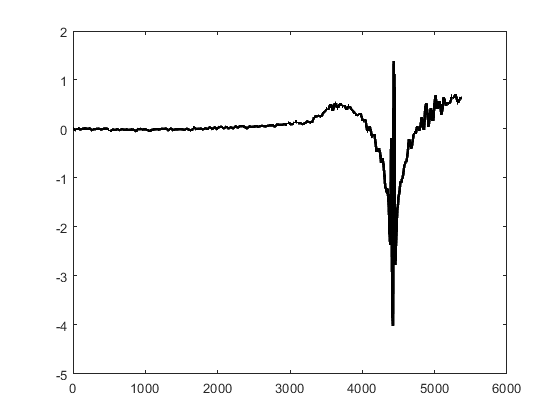

Test6_st40=(-521.2*521.2*0.001)*A.st40(411593:416968);
Test6_st40 = wdenoise(Test6_st40,5,'DenoisingMethod','BlockJS');
Test6_st40=detrend(Test6_st40,2);
Test6_st40=Test6_st40-mean(Test6_st40(1:500));

Time6_st40=A.Time(411597:420472);

figure
plot(Test6_st40,'k', 'Linewidth', 2)

## Inputs

N_T6=3;          %% the number of axles
v1_T6=28.16;     %% m/s
f_T6=200;         %% Hz
d1_T6=0;         %% m
d2_T6=4.93;      %% m
d3_T6=1.22;      %% m



Weights_T6=[15.600 21.280 21.280];


D1_vec_T6=[d1_T6 d1_T6+d2_T6 d1_T6+d2_T6+d3_T6];

c1_T6=D1_vec_T6(1)*f_T6/v1_T6;
c2_T6=D1_vec_T6(2)*f_T6/v1_T6;
c3_T6=D1_vec_T6(3)*f_T6/v1_T6;

C1_vec_T6=round([c1_T6 c2_T6 c3_T6]);

[row1_T6 col1_T6]=size(Test6_st40);         
k1_T6=row1_T6;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T6]=A_MATRIX(N_T6,k1_T6,C1_vec_T6,Weights_T6);


## Test 7 (3-axle and 30 mph)

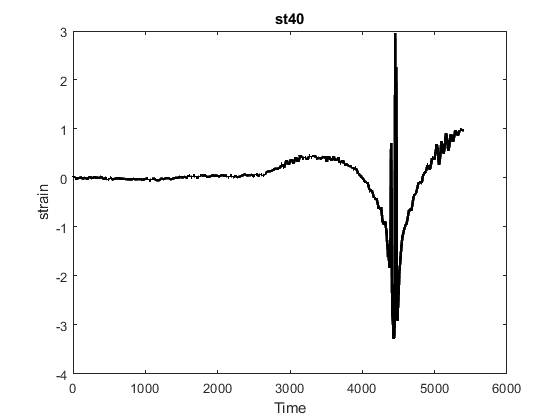

Test7_st40=(-521.2*521.2*0.001)*A.st40(511557:516960);
Test7_st40 = wdenoise(Test7_st40,5,'DenoisingMethod','BlockJS');
Test7_st40=detrend(Test7_st40,2);
Test7_st40=Test7_st40-mean(Test7_st40(1:500));
Time7_st40=A.Time(511557:520460);

figure

plot(Test7_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_T7=3;          %% the number of axles
v1_T7=17.1;     %% m/s
f_T7=200;         %% Hz
d1_T7=0;         %% m
d2_T7=4.82;      %% m
d3_T7=1.31;      %% m



Weights_T7=[15.600 21.280 21.280];

D1_vec_T7=[d1_T7 d1_T7+d2_T7 d1_T7+d2_T7+d3_T7];

c1_T7=D1_vec_T7(1)*f_T7/v1_T7;
c2_T7=D1_vec_T7(2)*f_T7/v1_T7;
c3_T7=D1_vec_T7(3)*f_T7/v1_T7;

C1_vec_T7=round([c1_T7 c2_T7 c3_T7]);

[row1_T7 col1_T7]=size(Test7_st40);         
k1_T7=row1_T7;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T7]=A_MATRIX(N_T7,k1_T7,C1_vec_T7,Weights_T7);


## Test 8 (3-axle and 30 mph)

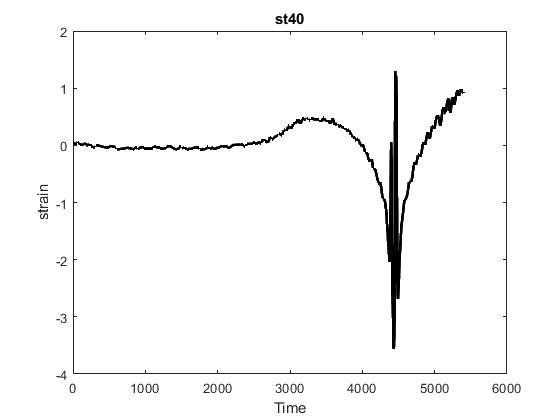



Test8_st40=(-521.2*521.2*0.001)*A.st40(556493:561895);
Test8_st40 = wdenoise(Test8_st40,5,'DenoisingMethod','BlockJS');
Test8_st40=detrend(Test8_st40,2);
Test8_st40=Test8_st40-mean(Test8_st40(1:500));


figure

plot(Test8_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_T8=3;          %% the number of axles
v1_T8=16.56;     %% m/s
f_T8=200;         %% Hz
d1_T8=0;         %% m
d2_T8=4.66;      %% m
d3_T8=1.24;      %% m



Weights_T8=[15.600 21.280 21.280];


D1_vec_T8=[d1_T8 d1_T8+d2_T8 d1_T8+d2_T8+d3_T8];

c1_T8=D1_vec_T8(1)*f_T8/v1_T8;
c2_T8=D1_vec_T8(2)*f_T8/v1_T8;
c3_T8=D1_vec_T8(3)*f_T8/v1_T8;

C1_vec_T8=round([c1_T8 c2_T8 c3_T8]);

[row1_T8 col1_T8]=size(Test8_st40);         
k1_T8=row1_T8;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_T8]=A_MATRIX(N_T8,k1_T8,C1_vec_T8,Weights_T8);

## Influence Line 

For IL computation, Tests 5-9 were used that are all 3-axle trucks

Inf_Line=inv(A_mat_T5'*A_mat_T5+A_mat_T6'*A_mat_T6+A_mat_T7'*A_mat_T7+A_mat_T8'*A_mat_T8)*(A_mat_T5'*Test5_st40+A_mat_T6'*Test6_st40+A_mat_T7'*Test7_st40+A_mat_T8'*Test8_st40);

## Check the IL

Here, using the computed IL, we reconstruct the strain response and compare it with the original strain to see how the IL procedure works.

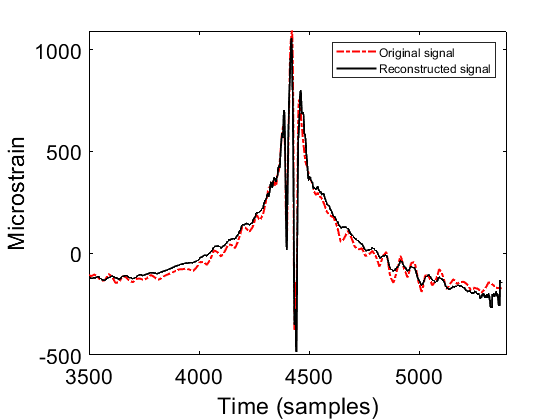

Strain_T6=A_mat_T6*Inf_Line;  %%% Strain reconstruction


figure
plot(-521.2*521.2*0.001*Test6_st40,'-.r', 'Linewidth', 1.5)

hold on

plot((-521.2*521.2*0.001*Strain_T6),'k', 'Linewidth', 1.5)
ylabel('Microstrain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';
% title('Estimated signal')
legend('Original signal','Reconstructed signal')

xlim([3500 5400])

As explained before, the second group of trucks is the construction trucks and the following tests are related to them (all 3-axle trucks)

## Evaluation 1 (3-axle and 25 mph) (Driver's name= Ricky, Time: 9:07 am)

Eva=readtimetable('B.csv');
datetime.setDefaultFormats('default','hh:mm:ss.SS')
Eva

Eva = 1048574×1 timetable
      Column1      Column5
    ___________    _______

    09:00:00.01    2.6702 
    09:00:00.02    2.6704 
    09:00:00.03    2.6703 
    09:00:00.04    2.6701 
    09:00:00.05      2.67 
    09:00:00.06      2.67 
    09:00:00.07    2.6702 
    09:00:00.08      2.67 
    09:00:00.09    2.6703 
    09:00:00.10    2.6701 
    09:00:00.11    2.6702 
    09:00:00.12    2.6703 
    09:00:00.13    2.6698 
    09:00:00.14    2.6702 
    09:00:00.15    2.6701 
    09:00:00.16    2.6702 


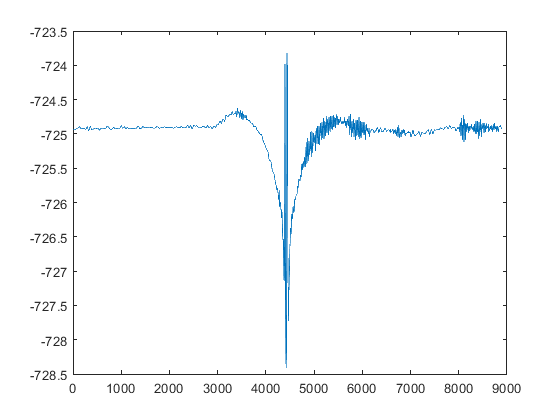


Eva1_st40=(-521.2*521.2*0.001)*Eva.Column5(40906:49791);
% Eva1_st40=(-521.2*521.2*0.001)*Eva.Column5(40903:46342);

Eva1_st40 = wdenoise(Eva1_st40,5,'DenoisingMethod','BlockJS');

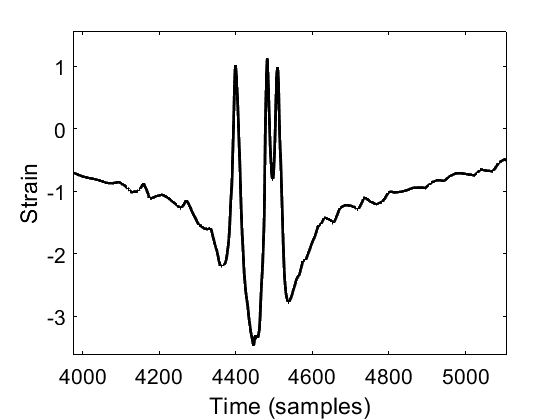

Eva1_st40=detrend(Eva1_st40);
Eva1_st40=Eva1_st40-mean(Eva1_st40(1:500));
Eva1_st40 = interp(Eva1_st40,2);


Eva1_st40=Eva1_st40(4392:9831);


figure

plot(Eva1_st40,'k', 'Linewidth', 2)
ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva1=3;          %% the number of axles
v1_Eva1=10.48;     %% m/s
f_Eva1=200;         %% Hz
d1_Eva1=0;         %% m
d2_Eva1=4.23;      %% m
d3_Eva1=1.43;      %% m

Weights_Eva1=[15.600 21.280 21.280];
D1_vec_Eva1=[d1_Eva1 d1_Eva1+d2_Eva1 d1_Eva1+d2_Eva1+d3_Eva1];

c1_Eva1=D1_vec_Eva1(1)*f_Eva1/v1_Eva1;
c2_Eva1=D1_vec_Eva1(2)*f_Eva1/v1_Eva1;
c3_Eva1=D1_vec_Eva1(3)*f_Eva1/v1_Eva1;

C1_vec_Eva1=round([c1_Eva1 c2_Eva1 c3_Eva1]);

[row1_Eva1 col1_Eva1]=size(Eva1_st40);         
k1_Eva1=row1_Eva1;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva1]=A_MATRIX(N_Eva1,k1_Eva1,C1_vec_Eva1,Weights_Eva1);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva1] = B_MATRIX(N_Eva1,k1_Eva1,Inf_Line,C1_vec_Eva1);
Weights_estimated_Eva1=inv((B_mat_Eva1'*B_mat_Eva1))*(B_mat_Eva1'*Eva1_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva1=Weights_estimated_Eva1(1)+Weights_estimated_Eva1(2)+Weights_estimated_Eva1(3)

TotalWeight_Eva1 = 45.8594

## Evaluation 2 (Driver's name= Ricky, time= 9:35 am)

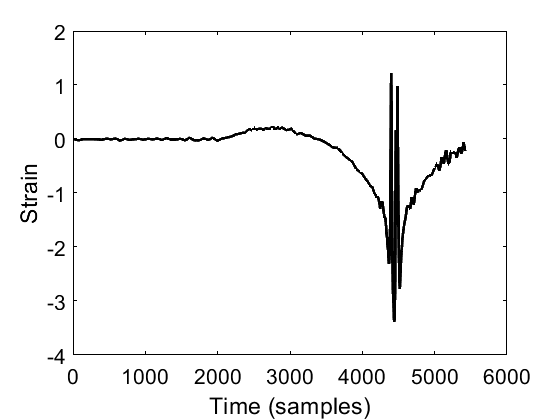

Eva2_st40=(-521.2*521.2*0.001)*Eva.Column5(205905:225844);
Eva2_st40 = wdenoise(Eva2_st40,5,'DenoisingMethod','BlockJS');
Eva2_st40=detrend(Eva2_st40);
Eva2_st40=Eva2_st40-mean(Eva2_st40(1:500));
Eva2_st40 = interp(Eva2_st40,2);
Eva2_st40=Eva2_st40(1472:6893);



figure

plot(Eva2_st40,'k', 'Linewidth', 2)
ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva2=3;          %% the number of axles
v1_Eva2=12.11;     %% m/s
f_Eva2=200;         %% Hz
d1_Eva2=0;         %% m
d2_Eva2=4.04;      %% m
d3_Eva2=1.41;      %% m

Weights_Eva2=[15.600 21.280 21.280];
D1_vec_Eva2=[d1_Eva2 d1_Eva2+d2_Eva2 d1_Eva2+d2_Eva2+d3_Eva2];

c1_Eva2=D1_vec_Eva2(1)*f_Eva2/v1_Eva2;
c2_Eva2=D1_vec_Eva2(2)*f_Eva2/v1_Eva2;
c3_Eva2=D1_vec_Eva2(3)*f_Eva2/v1_Eva2;

C1_vec_Eva2=round([c1_Eva2 c2_Eva2 c3_Eva2]);

[row1_Eva2 col1_Eva2]=size(Eva2_st40);         
k1_Eva2=row1_Eva2;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva2]=A_MATRIX(N_Eva2,k1_Eva2,C1_vec_Eva2,Weights_Eva2);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva2] = B_MATRIX(N_Eva2,k1_Eva2,Inf_Line,C1_vec_Eva2);
Weights_estimated_Eva2=inv((B_mat_Eva2'*B_mat_Eva2))*(B_mat_Eva2'*Eva2_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva2=Weights_estimated_Eva2(1)+Weights_estimated_Eva2(2)+Weights_estimated_Eva2(3)

TotalWeight_Eva2 = 47.6019

## Evaluation 3 (Driver's name= Ricky, time= 10:34 am)

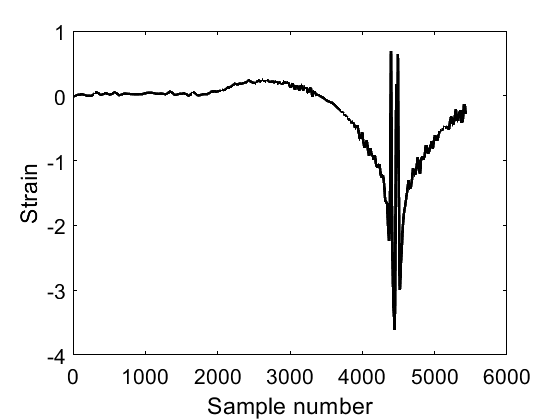

Eva3_st40=(-521.2*521.2*0.001)*Eva.Column5(555907:565846);
Eva3_st40 = wdenoise(Eva3_st40,5,'DenoisingMethod','BlockJS');
Eva3_st40=detrend(Eva3_st40);
Eva3_st40=Eva3_st40-mean(Eva3_st40(1:500));
Eva3_st40 = interp(Eva3_st40,2);
Time_Eva3_st40_st40=Eva.Column1(555906:565941);

Eva3_st40=Eva3_st40(4618:10046);


figure

plot(Eva3_st40,'k', 'Linewidth', 2)
ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Sample number','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')

ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva3=3;          %% the number of axles
v1_Eva3=11.28;     %% m/s
f_Eva3=200;         %% Hz
d1_Eva3=0;         %% m
d2_Eva3=4.06;      %% m
d3_Eva3=1.43;      %% m

Weights_Eva3=[15.600 21.280 21.280];
D1_vec_Eva3=[d1_Eva3 d1_Eva3+d2_Eva3 d1_Eva3+d2_Eva3+d3_Eva3];

c1_Eva3=D1_vec_Eva3(1)*f_Eva3/v1_Eva3;
c2_Eva3=D1_vec_Eva3(2)*f_Eva3/v1_Eva3;
c3_Eva3=D1_vec_Eva3(3)*f_Eva3/v1_Eva3;

C1_vec_Eva3=round([c1_Eva3 c2_Eva3 c3_Eva3]);

[row1_Eva3 col1_Eva3]=size(Eva3_st40);         
k1_Eva3=row1_Eva3;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva3]=A_MATRIX(N_Eva3,k1_Eva3,C1_vec_Eva3,Weights_Eva3);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva3] = B_MATRIX(N_Eva3,k1_Eva3,Inf_Line,C1_vec_Eva3);
Weights_estimated_Eva3=inv((B_mat_Eva3'*B_mat_Eva3))*(B_mat_Eva3'*Eva3_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva3=Weights_estimated_Eva3(1)+Weights_estimated_Eva3(2)+Weights_estimated_Eva3(3)

TotalWeight_Eva3 = 48.9072

## Evaluation 4 (Driver's name= Ricky, time= 11:14 am)

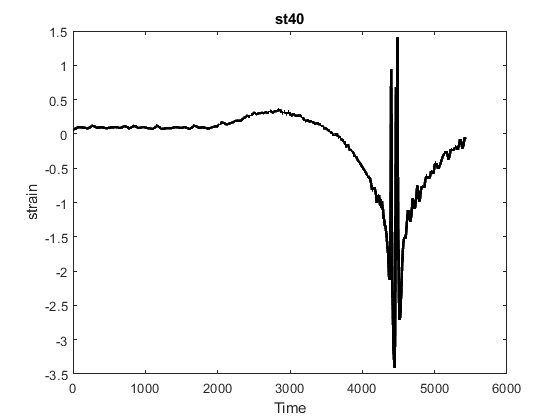

Eva4_st40=(-521.2*521.2*0.001)*Eva.Column5(778906:792845);

Eva4_st40 = wdenoise(Eva4_st40,5,'DenoisingMethod','BlockJS');
Eva4_st40=detrend(Eva4_st40);
Eva4_st40=Eva4_st40-mean(Eva4_st40(1:500));
Eva4_st40 = interp(Eva4_st40,2);
Time_Eva4_st40_st40=Eva.Column1(778906:792845);

Eva4_st40=Eva4_st40(13568:18989);


figure

plot(Eva4_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_Eva4=3;          %% the number of axles
v1_Eva4=12.19;     %% m/s
f_Eva4=200;         %% Hz
d1_Eva4=0;         %% m
d2_Eva4=4.06;      %% m
d3_Eva4=1.42;      %% m

Weights_Eva4=[15.600 21.280 21.280];
D1_vec_Eva4=[d1_Eva4 d1_Eva4+d2_Eva4 d1_Eva4+d2_Eva4+d3_Eva4];

c1_Eva4=D1_vec_Eva4(1)*f_Eva4/v1_Eva4;
c2_Eva4=D1_vec_Eva4(2)*f_Eva4/v1_Eva4;
c3_Eva4=D1_vec_Eva4(3)*f_Eva4/v1_Eva4;

C1_vec_Eva4=round([c1_Eva4 c2_Eva4 c3_Eva4]);

[row1_Eva4 col1_Eva4]=size(Eva4_st40);         
k1_Eva4=row1_Eva4;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva4]=A_MATRIX(N_Eva4,k1_Eva4,C1_vec_Eva4,Weights_Eva4);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva4] = B_MATRIX(N_Eva4,k1_Eva4,Inf_Line,C1_vec_Eva4);
Weights_estimated_Eva4=inv((B_mat_Eva4'*B_mat_Eva4))*(B_mat_Eva4'*Eva4_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva4=Weights_estimated_Eva4(1)+Weights_estimated_Eva4(2)+Weights_estimated_Eva4(3)

TotalWeight_Eva4 = 51.2247

## Evaluation 5 (Driver's name= Ricky, 11:50 am)

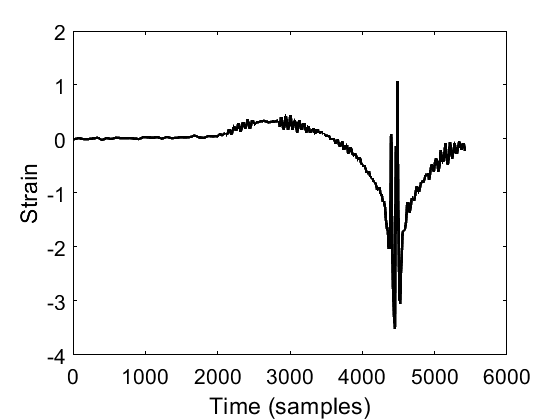

Eva5_st40=(-521.2*521.2*0.001)*Eva.Column5(1000906:1006000);
Eva5_st40 = wdenoise(Eva5_st40,5,'DenoisingMethod','BlockJS');
Eva5_st40=detrend(Eva5_st40);
Eva5_st40=Eva5_st40-mean(Eva5_st40(1:500));
Eva5_st40 = interp(Eva5_st40,2);
Time_Eva5_st40_st40=Eva.Column1(1000906:1006000);

Eva5_st40=Eva5_st40(891:6311);


figure

plot(Eva5_st40,'k', 'Linewidth', 2)

ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Time (samples)','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva5=3;          %% the number of axles
v1_Eva5=12.12;     %% m/s
f_Eva5=200;         %% Hz
d1_Eva5=0;         %% m
d2_Eva5=4.00;      %% m
d3_Eva5=1.41;      %% m

Weights_Eva5=[15.600 21.280 21.280];
D1_vec_Eva5=[d1_Eva5 d1_Eva5+d2_Eva5 d1_Eva5+d2_Eva5+d3_Eva5];

c1_Eva5=D1_vec_Eva5(1)*f_Eva5/v1_Eva5;
c2_Eva5=D1_vec_Eva5(2)*f_Eva5/v1_Eva5;
c3_Eva5=D1_vec_Eva5(3)*f_Eva5/v1_Eva5;

C1_vec_Eva5=round([c1_Eva5 c2_Eva5 c3_Eva5]);

[row1_Eva5 col1_Eva5]=size(Eva5_st40);         
k1_Eva5=row1_Eva5;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva5]=A_MATRIX(N_Eva5,k1_Eva5,C1_vec_Eva5,Weights_Eva5);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva5] = B_MATRIX(N_Eva5,k1_Eva5,Inf_Line,C1_vec_Eva5);
Weights_estimated_Eva5=inv((B_mat_Eva5'*B_mat_Eva5))*(B_mat_Eva5'*Eva5_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva5=Weights_estimated_Eva5(1)+Weights_estimated_Eva5(2)+Weights_estimated_Eva5(3)

TotalWeight_Eva5 = 51.4419

## Evaluation 6 (Tim 9:28)

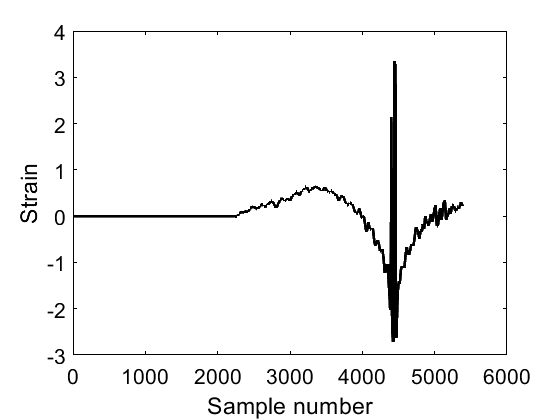

Eva6_st40=(-521.2*521.2*0.001)*Eva.Column5(159906:170906);
Eva6_st40 = wdenoise(Eva6_st40,5,'DenoisingMethod','BlockJS');

Eva6_st40=detrend(Eva6_st40);



Eva6_st40=Eva6_st40(2436:end);
Eva6_st40=Eva6_st40';
Eva6_st40=[Eva6_st40(1)*(ones(1,3313)) Eva6_st40];
Eva6_st40=Eva6_st40';
Eva6_st40=Eva6_st40-mean(Eva6_st40(1:500));
Eva6_st40 = interp(Eva6_st40,2);
Eva6_st40=Eva6_st40(4398:9787);


figure

plot(Eva6_st40,'k', 'Linewidth', 2)
ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Sample number','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva6=3;          %% the number of axles
v1_Eva6=19.9;     %% m/s
% v1_Eva6=20.9;     %% m/s
f_Eva6=200;         %% Hz
d1_Eva6=0;         %% m
d2_Eva6=4.38;      %% m
d3_Eva6=1.39;      %% m

Weights_Eva6=[15.600 21.280 21.280];
D1_vec_Eva6=[d1_Eva6 d1_Eva6+d2_Eva6 d1_Eva6+d2_Eva6+d3_Eva6];

c1_Eva6=D1_vec_Eva6(1)*f_Eva6/v1_Eva6;
c2_Eva6=D1_vec_Eva6(2)*f_Eva6/v1_Eva6;
c3_Eva6=D1_vec_Eva6(3)*f_Eva6/v1_Eva6;

C1_vec_Eva6=round([c1_Eva6 c2_Eva6 c3_Eva6]);

[row1_Eva6 col1_Eva6]=size(Eva6_st40);         
k1_Eva6=row1_Eva6;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva6]=A_MATRIX(N_Eva6,k1_Eva6,C1_vec_Eva6,Weights_Eva6);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva6] = B_MATRIX(N_Eva6,k1_Eva6,Inf_Line,C1_vec_Eva6);
Weights_estimated_Eva6=inv((B_mat_Eva6'*B_mat_Eva6))*(B_mat_Eva6'*Eva6_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva6=Weights_estimated_Eva6(1)+Weights_estimated_Eva6(2)+Weights_estimated_Eva6(3)

TotalWeight_Eva6 = 50.8203

## Evaluation 7 (Driver's name=Tim_ time= 9:58 am)

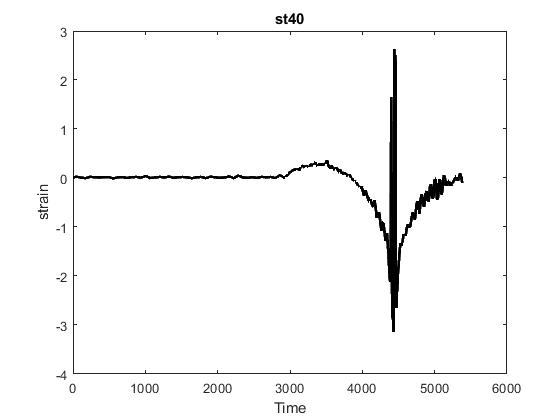

Eva7_st40=(-521.2*521.2*0.001)*Eva.Column5(340906:350906);
Eva7_st40 = wdenoise(Eva7_st40,5,'DenoisingMethod','BlockJS');

Eva7_st40=detrend(Eva7_st40);
Eva7_st40=Eva7_st40-mean(Eva7_st40(1:500));
Eva7_st40 = interp(Eva7_st40,2);
Time_Eva7_st40_st40=Eva.Column1(340907:350906);

Eva7_st40=Eva7_st40(3424:8811);


figure
plot(Eva7_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_Eva7=3;          %% the number of axles
v1_Eva7=19.96;     %% m/s
f_Eva7=200;         %% Hz
d1_Eva7=0;         %% m
d2_Eva7=4.26;      %% m
d3_Eva7=1.33;      %% m

Weights_Eva7=[15.600 21.280 21.280];
D1_vec_Eva7=[d1_Eva7 d1_Eva7+d2_Eva7 d1_Eva7+d2_Eva7+d3_Eva7];

c1_Eva7=D1_vec_Eva7(1)*f_Eva7/v1_Eva7;
c2_Eva7=D1_vec_Eva7(2)*f_Eva7/v1_Eva7;
c3_Eva7=D1_vec_Eva7(3)*f_Eva7/v1_Eva7;

C1_vec_Eva7=round([c1_Eva7 c2_Eva7 c3_Eva7]);

[row1_Eva7 col1_Eva7]=size(Eva7_st40);         
k1_Eva7=row1_Eva7;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva7]=A_MATRIX(N_Eva7,k1_Eva7,C1_vec_Eva7,Weights_Eva7);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva7] = B_MATRIX(N_Eva7,k1_Eva7,Inf_Line,C1_vec_Eva7);
Weights_estimated_Eva7=inv((B_mat_Eva7'*B_mat_Eva7))*(B_mat_Eva7'*Eva7_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva7=Weights_estimated_Eva7(1)+Weights_estimated_Eva7(2)+Weights_estimated_Eva7(3)

TotalWeight_Eva7 = 47.1197

## Evaluation 8 (Driver's name= Tim_time= 10:40 am)

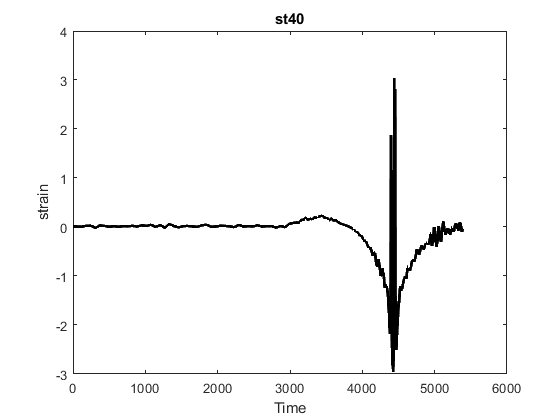

Eva8_st40=(-521.2*521.2*0.001)*Eva.Column5(588906:600906);

Eva8_st40 = wdenoise(Eva8_st40,5,'DenoisingMethod','BlockJS');
Eva8_st40=detrend(Eva8_st40);
Eva8_st40=Eva8_st40-mean(Eva8_st40(1:500));
Eva8_st40 = interp(Eva8_st40,2);
Time_Eva8_st40_st40=Eva.Column1(588904:600904);

Eva8_st40=Eva8_st40(5335:10723);


figure

plot(Eva8_st40,'k', 'Linewidth', 2)
title('st40')
xlabel('Time')
ylabel('strain')

## Inputs

N_Eva8=3;          %% the number of axles
v1_Eva8=19.66;     %% m/s
f_Eva8=200;         %% Hz
d1_Eva8=0;         %% m
d2_Eva8=4.26;      %% m
d3_Eva8=1.31;      %% m

Weights_Eva8=[15.600 21.280 21.280];
D1_vec_Eva8=[d1_Eva8 d1_Eva8+d2_Eva8 d1_Eva8+d2_Eva8+d3_Eva8];

c1_Eva8=D1_vec_Eva8(1)*f_Eva8/v1_Eva8;
c2_Eva8=D1_vec_Eva8(2)*f_Eva8/v1_Eva8;
c3_Eva8=D1_vec_Eva8(3)*f_Eva8/v1_Eva8;

C1_vec_Eva8=round([c1_Eva8 c2_Eva8 c3_Eva8]);

[row1_Eva8 col1_Eva8]=size(Eva8_st40);         
k1_Eva8=row1_Eva8;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva8]=A_MATRIX(N_Eva8,k1_Eva8,C1_vec_Eva8,Weights_Eva8);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva8] = B_MATRIX(N_Eva8,k1_Eva8,Inf_Line,C1_vec_Eva8);
Weights_estimated_Eva8=inv((B_mat_Eva8'*B_mat_Eva8))*(B_mat_Eva8'*Eva8_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva8=Weights_estimated_Eva8(1)+Weights_estimated_Eva8(2)+Weights_estimated_Eva8(3)

TotalWeight_Eva8 = 45.0944

## Evaluation 9 (Tim_11:17)

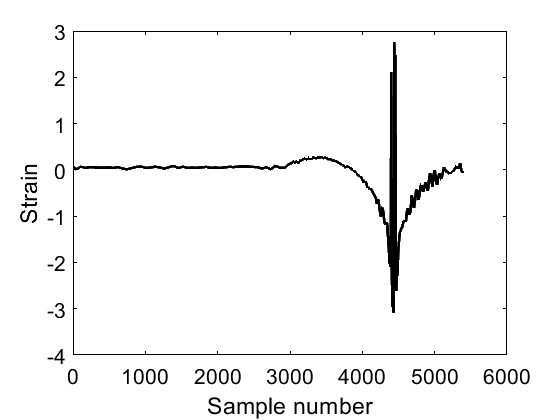

Eva9_st40=(-521.2*521.2*0.001)*Eva.Column5(802906:817906);

Eva9_st40 = wdenoise(Eva9_st40,5,'DenoisingMethod','BlockJS');
Eva9_st40=detrend(Eva9_st40);
Eva9_st40=Eva9_st40-mean(Eva9_st40(1:500));
Eva9_st40 = interp(Eva9_st40,2);
Time_Eva9_st40_st40=Eva.Column1(802906:817906);

Eva9_st40=Eva9_st40(9822:15209);


figure

plot(Eva9_st40,'k', 'Linewidth', 2)
xlabel('Time')
ylabel('strain')
ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Sample number','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva9=3;          %% the number of axles
v1_Eva9=19.9;     %% m/s
f_Eva9=200;         %% Hz
d1_Eva9=0;         %% m
d2_Eva9=4.18;      %% m
d3_Eva9=1.39;      %% m

Weights_Eva9=[15.600 21.280 21.280];
D1_vec_Eva9=[d1_Eva9 d1_Eva9+d2_Eva9 d1_Eva9+d2_Eva9+d3_Eva9];

c1_Eva9=D1_vec_Eva9(1)*f_Eva9/v1_Eva9;
c2_Eva9=D1_vec_Eva9(2)*f_Eva9/v1_Eva9;
c3_Eva9=D1_vec_Eva9(3)*f_Eva9/v1_Eva9;

C1_vec_Eva9=round([c1_Eva9 c2_Eva9 c3_Eva9]);

[row1_Eva9 col1_Eva9]=size(Eva9_st40);         
k1_Eva9=row1_Eva9;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva9]=A_MATRIX(N_Eva9,k1_Eva9,C1_vec_Eva9,Weights_Eva9);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva9] = B_MATRIX(N_Eva9,k1_Eva9,Inf_Line,C1_vec_Eva9);
Weights_estimated_Eva9=inv((B_mat_Eva9'*B_mat_Eva9))*(B_mat_Eva9'*Eva9_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva9=Weights_estimated_Eva9(1)+Weights_estimated_Eva9(2)+Weights_estimated_Eva9(3)

TotalWeight_Eva9 = 47.4666

## Evaluation 10 (Driver's name=Tim_ time=11:50 am)

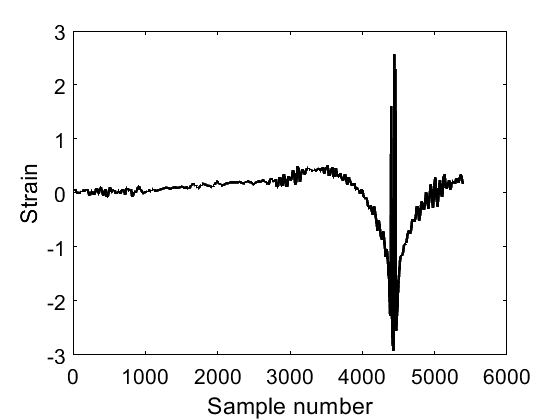


Eva10_st40=(-521.2*521.2*0.001)*Eva.Column5(1005091:1008827);
Eva10_st40 = wdenoise(Eva10_st40,5,'DenoisingMethod','BlockJS');

Eva10_st40=detrend(Eva10_st40);
Eva10_st40=Eva10_st40-mean(Eva10_st40(1:500));
Eva10_st40 = interp(Eva10_st40,2);


Eva10_st40=Eva10_st40(1094:6483);


figure

plot(Eva10_st40,'k', 'Linewidth', 2)

xlabel('Time')
ylabel('strain')
ylabel('Strain','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
xlabel('Sample number','FontSize', 16 ,"FontName",'Times New Roman',"Color",'k')
ax = gca;
ax.YAxis.Color = 'k';
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
ax.XAxis.Color = 'k';

## Inputs

N_Eva10=3;          %% the number of axles
v1_Eva10=18.99;     %% m/s
f_Eva10=200;         %% Hz
d1_Eva10=0;         %% m
d2_Eva10=4.18;      %% m
d3_Eva10=1.33;      %% m

Weights_Eva10=[15.600 21.280 21.280];
D1_vec_Eva10=[d1_Eva10 d1_Eva10+d2_Eva10 d1_Eva10+d2_Eva10+d3_Eva10];

c1_Eva10=D1_vec_Eva10(1)*f_Eva10/v1_Eva10;
c2_Eva10=D1_vec_Eva10(2)*f_Eva10/v1_Eva10;
c3_Eva10=D1_vec_Eva10(3)*f_Eva10/v1_Eva10;

C1_vec_Eva10=round([c1_Eva10 c2_Eva10 c3_Eva10]);

[row1_Eva10 col1_Eva10]=size(Eva10_st40);         
k1_Eva10=row1_Eva10;                      %% Total number of scans

%%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
%%% Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)

[A_mat_Eva10]=A_MATRIX(N_Eva10,k1_Eva10,C1_vec_Eva10,Weights_Eva10);

% %%% This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), 
% %%% Influence line vector to create matrix B which will be used for weight estimation

[B_mat_Eva10] = B_MATRIX(N_Eva10,k1_Eva10,Inf_Line,C1_vec_Eva10);
Weights_estimated_Eva10=inv((B_mat_Eva10'*B_mat_Eva10))*(B_mat_Eva10'*Eva10_st40);
% TotalWeight=Weights_estimated(1)+Weights_estimated(2)+Weights_estimated(3)
TotalWeight_Eva10=Weights_estimated_Eva10(1)+Weights_estimated_Eva10(2)+Weights_estimated_Eva10(3)

TotalWeight_Eva10 = 50.9602

## Weight estimation of Tests 1-4 (5-axle trucks)

%%% T1
[B_mat_T1] = B_MATRIX(N_T1,k1_T1,Inf_Line,C1_vec_T1);
Weights_estimated_T1=inv((B_mat_T1'*B_mat_T1))*(B_mat_T1'*Test1_st40);
% TotalWeight_T1=Weights_estimated_T1(1)+Weights_estimated_T1(2)+Weights_estimated_T1(3)
TotalWeight=Weights_estimated_T1(1)+Weights_estimated_T1(2)+Weights_estimated_T1(3)+Weights_estimated_T1(4)+Weights_estimated_T1(5)

TotalWeight = 51.4252


%%% T2
[B_mat_T2] = B_MATRIX(N_T2,k1_T2,Inf_Line,C1_vec_T2);
Weights_estimated_T2=inv((B_mat_T2'*B_mat_T2))*(B_mat_T2'*Test2_st40);
% TotalWeight_T2=Weights_estimated_T2(1)+Weights_estimated_T2(2)+Weights_estimated_T2(3)
TotalWeight=Weights_estimated_T2(1)+Weights_estimated_T2(2)+Weights_estimated_T2(3)+Weights_estimated_T2(4)+Weights_estimated_T2(5)

TotalWeight = 48.7633


%%% T3
[B_mat_T3] = B_MATRIX(N_T3,k1_T3,Inf_Line,C1_vec_T3);
Weights_estimated_T3=inv((B_mat_T3'*B_mat_T3))*(B_mat_T3'*Test3_st40);
% TotalWeight_T3=Weights_estimated_T3(1)+Weights_estimated_T3(2)+Weights_estimated_T3(3)
TotalWeight=Weights_estimated_T3(1)+Weights_estimated_T3(2)+Weights_estimated_T3(3)+Weights_estimated_T3(4)+Weights_estimated_T3(5)

TotalWeight = 55.4311


%%% T4
[B_mat_T4] = B_MATRIX(N_T4,k1_T4,Inf_Line,C1_vec_T4);
Weights_estimated_T4=inv((B_mat_T4'*B_mat_T4))*(B_mat_T4'*Test4_st40);
% TotalWeight_T4=Weights_estimated_T4(1)+Weights_estimated_T4(2)+Weights_estimated_T4(3)
TotalWeight=Weights_estimated_T4(1)+Weights_estimated_T4(2)+Weights_estimated_T4(3)+Weights_estimated_T4(4)+Weights_estimated_T4(5)

TotalWeight = 57.9485